# Dimensionamento monoParamétrico nFNC

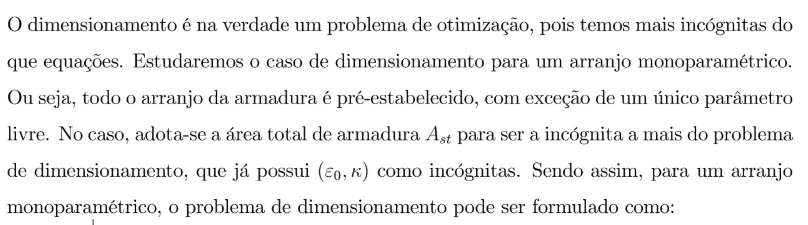

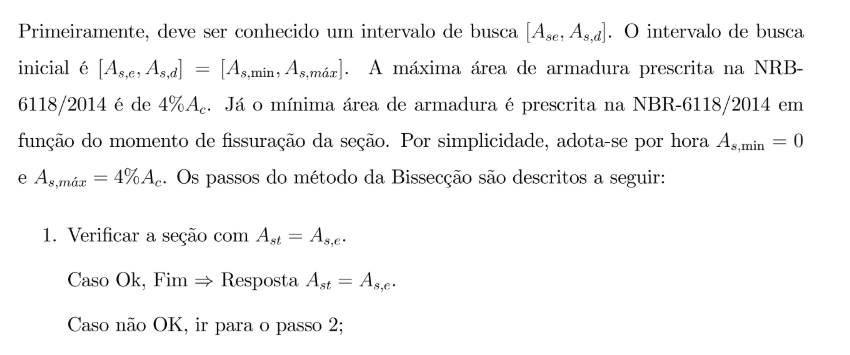

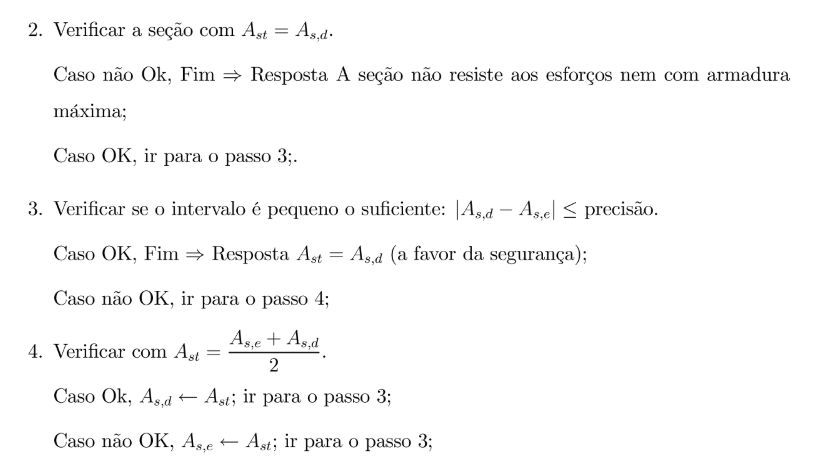

clear;
gamaf = 1.4;
gamac = 1.4;
gamas = 1.15;
Es = 210*10^3;


### Definição do Material e da Geometria

tipoc = 60; %definicoes de material %esta em MPa
tipos = 50; %nao esta em MPa

b = 0.25; %variaveis de geometria retangular
h = 0.7;
A = b*h;
S = 0;

ytopo = +h/2;
ybase = -h/2;


### Definição da distribuição da Armadura

nc = 3;
ys = [-0.3 -0.22 0.3];
psi = [1/3 1/3 1/3]; %Asi/Ast

### Definição dos params do problema

precisao = 10^-13;
tolerancia = 10^-13;
maxite = 1000;

### Definição dos esforços solicitantes (Não esqueça de majorar(multiplicar por gamaf))

Nd = 6.903; %2000 kN
Md = 0.0; %70000 kN.m

Inicialização do problema

[fyd,epsilonyd] = paramsaco(tipos,Es,gamas);
Asmin = 0.15*abs(Nd)*(10^-6)/fyd;
Asmax = 4*A/100;

Asd = Asmax;
Asc = Asmin;
As = Asmin*psi;

resultado = verificacaoFNC_func(tipoc, tipos, b,h,ytopo, ybase,nc,ys,As,Nd,Md,gamac,gamas,Es,precisao,tolerancia);


Execução do loop

if resultado(1) == true
    fprintf('DIMENSIONAMENTO COM ÁREA MÍNIMA POSSÍVEL, Área = %f cm^2"! \n', (sum(As)*10^6));
    fprintf('Sua configuração de deformações (epsilon0,k) = (%f,%f)\n', resultado(2), resultado(3));
else
    As = Asmax*psi;
    resultado = verificacaoFNC_func(tipoc, tipos, b,h,ytopo, ybase,nc,ys,As,Nd,Md,gamac,gamas,Es,precisao,tolerancia);
    if resultado(1) == false
        fprintf('DIMENSIONAMENTO COM ÁREA MÁXIMA IMPOSSÍVEL! Não encontramos um dimensionamento adequado');
    else
        i = 0;

    while (i <= maxite)
        % Calcular a área total como o ponto médio de Asd e Asc
        As_total = (Asc + Asd) / 2;
        
        % Ajustar a área com o fator psi (assumindo psi como dado previamente)
        As = As_total * psi;
        
        % Verificar se a área atual satisfaz as condições
        resultado = verificacaoFNC_func(tipoc, tipos, b,h,ytopo, ybase,nc,ys,As,Nd,Md,gamac,gamas,Es,precisao,tolerancia);
        
        % Checar se a condição de convergência foi atingida
        if abs(Asd - Asc) <= precisao 
            Area_minima = Asd; % A área mínima é o valor convergido
            fprintf('A área mínima é %f cm^2\n', Area_minima*10^4);
            fprintf('(e0,k) = (%f,%f), \n', resultado(2), resultado(3));
            fprintf('%g iterações, %g na última tentativa\n', i, resultado(4));
            return;
        end
        
        % Atualizar os limites com base na verificação
        if resultado(1) == true
            % Se a verificação for positiva, ajustar o limite superior
            Asd = As_total;
        else
            % Caso contrário, ajustar o limite inferior
            Asc = As_total;
        end
        
        % Incrementar o contador de iterações
        i = i + 1;
        end
            
        end
    end

A área mínima é 18.554103 cm^2


(e0,k) = (2.078698,1.018884), 


37 iterações, 10 na última tentativa
